# Figure 3.40 in book

Image smoothing

## Reading img

rgb_img = imread('lenna_RGB.tif');
hsv_img = rgb2hsv(rgb_img);

## Smoothing

segma = 10;
filter = fspecial('gaussian', 5, segma);
rgb_smoothed = cat( ...
    3, ...
    imfilter(rgb_img(:,:,1), filter), ...
    imfilter(rgb_img(:,:,2), filter), ...
    imfilter(rgb_img(:,:,3), filter)  ...
);

hsv_smoothed = hsv2rgb(cat( ...
    3, ...
    hsv_img(:,:,1), ...
    hsv_img(:,:,2), ...
    imfilter(hsv_img(:,:,3), filter) ...
));
hsv_smoothed = uint8(rescale(hsv_smoothed, 0, 255));

## Plotting

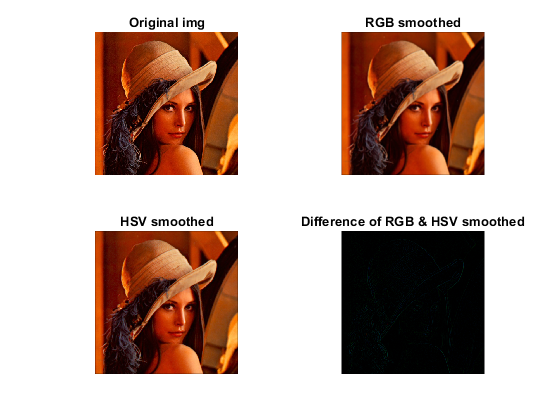

figure(1);
subplot(2,2,1); imshow(rgb_img);                    title('Original img');
subplot(2,2,2); imshow(rgb_smoothed);               title('RGB smoothed');
subplot(2,2,3); imshow(hsv_smoothed);               title('HSV smoothed');
subplot(2,2,4); imshow(rgb_smoothed-hsv_smoothed);  title('Difference of RGB & HSV smoothed');